% Before you run this code, make sure that you are in the right directory.
%
% First, download the zip files containing code and data for this unit, from 
% the lectures web page (accessible from the course website).
% 
% Second, unzip the zip files.
%
% Third, modify the addpath and cd commands in the beginning of the code,
% to reflect the locations of code and data on your computer
%
% Now you can copy lines from this script file and paste them to Matlab's
% command window.

% The addpath and cd lines are the only lines in the code that you may have
% to change, in order to make the rest of the code work. Adjust
% the paths to reflect the locations where you have stored the code 
% and data in your computer.

restoredefaultpath;
clear all;
close all;

addpath ../00_common/00_detection
addpath ../00_common/00_images
addpath ../00_common/00_utilities
addpath ../../Data/00_common_data/frgc2_b
addpath ../../Data/00_common_data
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Rectangle filters

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

type 1

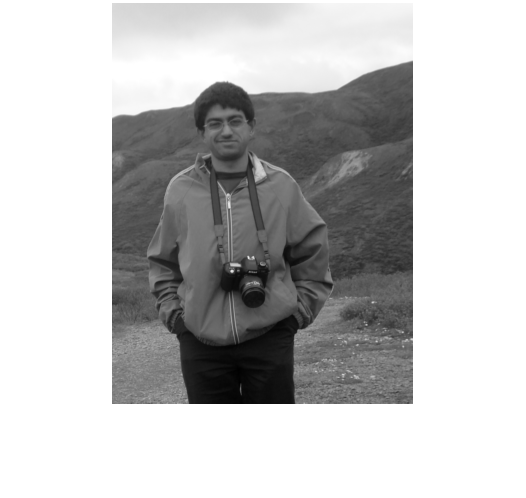

clear; close all;
photo = read_gray('faces5.bmp');
figure(1); imshow(photo, []);

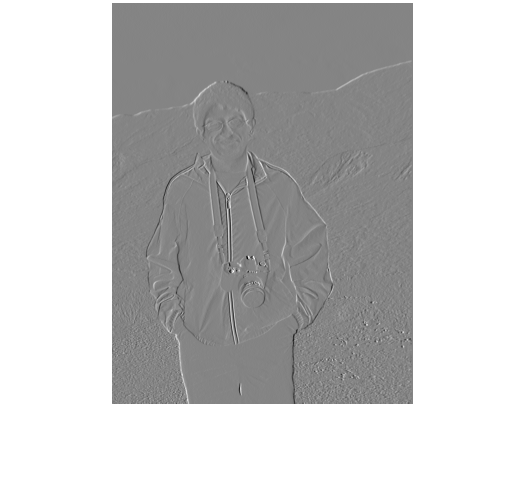

rec_filter = rectangle_filter1(1, 1);
result = imfilter(photo, rec_filter, 'same', 'symmetric');
figure(2); imshow(result, []);

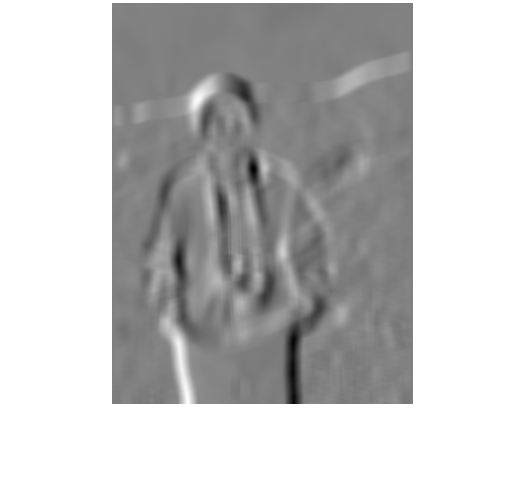


rec_filter2 = rectangle_filter1(20, 10);
result2 = imfilter(photo, rec_filter2, 'same', 'symmetric');
figure(3); imshow(result2, []);

type 2

clear; close all;
photo = read_gray('faces5.bmp');
figure(1); imshow(photo, []);

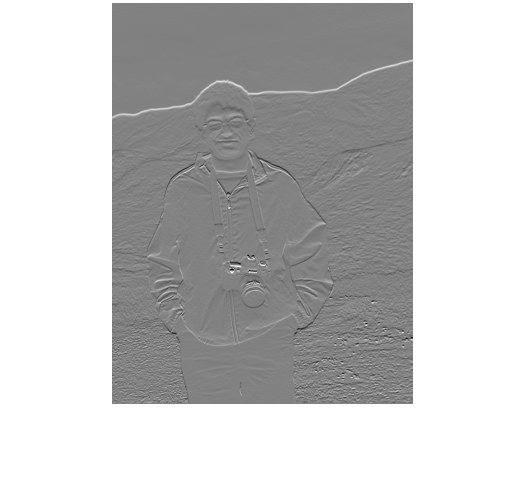

rec_filter = rectangle_filter2(1, 1);
result = imfilter(photo, rec_filter, 'same', 'symmetric');
figure(2); imshow(result, []);

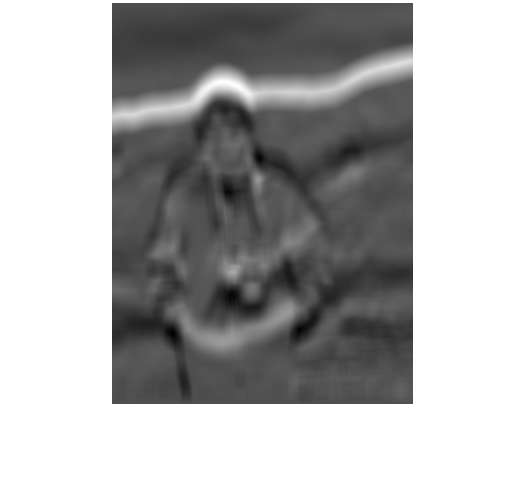


rec_filter2 = rectangle_filter2(20, 10);
result2 = imfilter(photo, rec_filter2, 'same', 'symmetric');
figure(3); imshow(result2, []);

type 3

clear; close all;
photo = read_gray('faces5.bmp');
figure(1); imshow(photo, []);

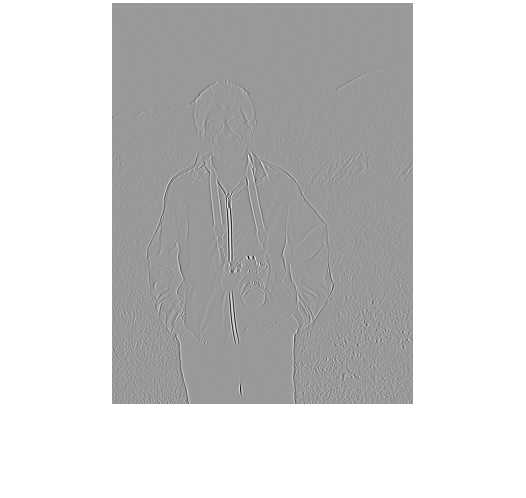

rec_filter = rectangle_filter3(1, 1);
result = imfilter(photo, rec_filter, 'same', 'symmetric');
figure(2); imshow(result, []);

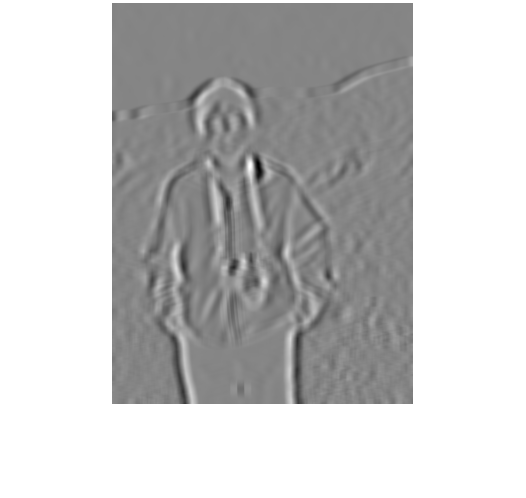


rec_filter2 = rectangle_filter3(10, 7);
result2 = imfilter(photo, rec_filter2, 'same', 'symmetric');
figure(3); imshow(result2, []);

type 4

clear; close all;
photo = read_gray('faces5.bmp');
figure(1); imshow(photo, []);

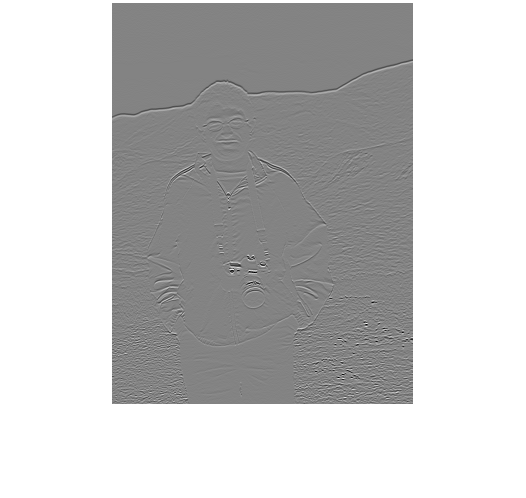

rec_filter = rectangle_filter4(1, 1);
result = imfilter(photo, rec_filter, 'same', 'symmetric');
figure(2); imshow(result, []);

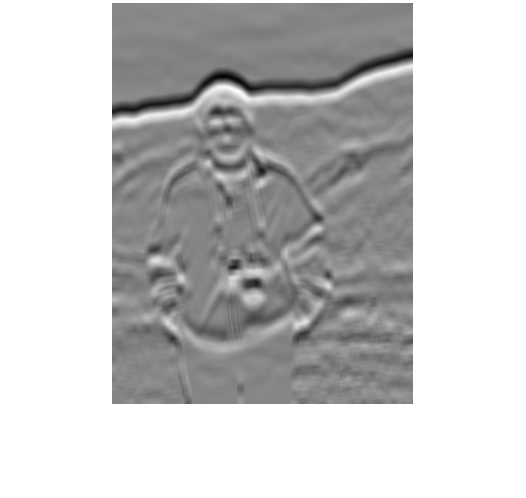


rec_filter2 = rectangle_filter4(10, 7);
result2 = imfilter(photo, rec_filter2, 'same', 'symmetric');
figure(3); imshow(result2, []);

type 5

clear; close all;
photo = read_gray('faces5.bmp');
figure(1); imshow(photo, []);

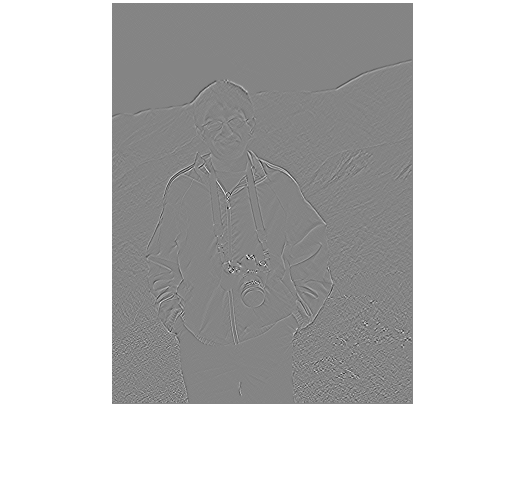

rec_filter = rectangle_filter5(1, 1);
result = imfilter(photo, rec_filter, 'same', 'symmetric');
figure(2); imshow(result, []);

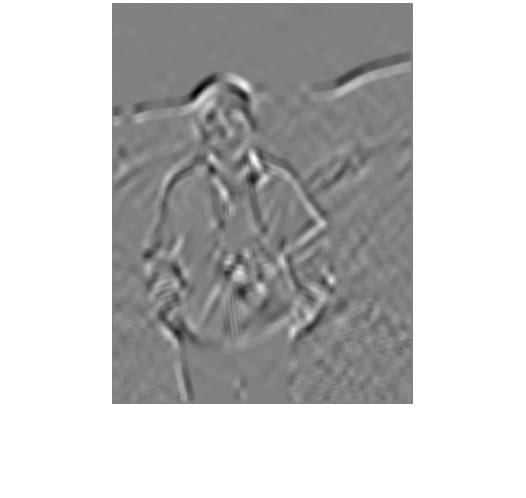


rec_filter2 = rectangle_filter5(10, 7);
result2 = imfilter(photo, rec_filter2, 'same', 'symmetric');
figure(3); imshow(result2, []);

% computing the integral image of some small input

clear; close all;
a = [1 2
     3 4
     5 6];
 
b = integral_image(a)

b =      1     3
     4    10
     9    21


clear; close all;
A = read_gray('faces5.bmp');
figure(1); imshow(A, []);

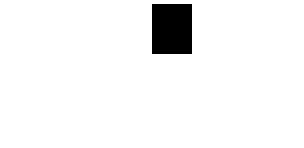

B = integral_image(A);

F = rectangle_filter1(50, 40);
figure(2); imshow(F, []);


tic; responses = imfilter(A, F, 'same', 'symmetric'); toc

Elapsed time is 0.164564 seconds.


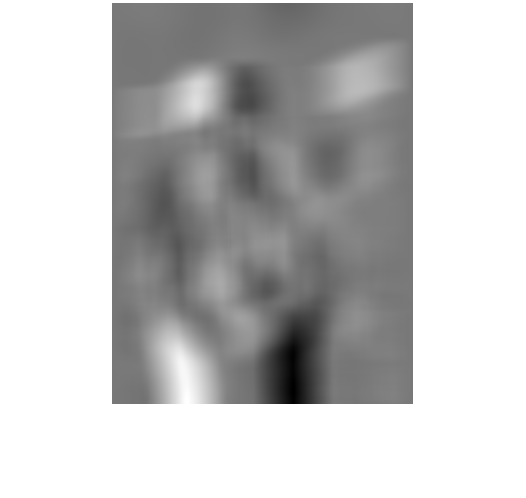

figure(3); imshow(responses, []);

responses(125, 240)

ans = 1.1854e+04

sum(sum(A(101:150, 201:280) .* F))

ans = 11854

sum(sum(A(101:150, 201:240) )) - sum(sum(A(101:150, 241:280)))

ans = 11854

tic; sum(sum(A(101:150, 201:240))); toc

Elapsed time is 0.000578 seconds.



tic; B(150,240)+B(100,200)-B(150,200)-B(100,240); toc

Elapsed time is 0.000102 seconds.


clear all;
load examples1000;

% testing evaluation of a random classifier of type 1.

wc = generate_classifier1(face_vertical, face_horizontal); 
disp(wc); 

    {1×4 double}    {1×4 double}    {[1]}    {[-1]}    {[17]}    {[10]}    {[3]}    {[6]}    {17×20 double}



disp(wc{1}); 

     3    19     6    15



disp(wc{2});

     3    19    16    25




% disp(wc{9});

index = 1;
face = faces(:,:,index);
integral = face_integrals(:, :, index);

response = eval_weak_classifier(wc, integral)

response = 1.1412e+03


% verification:
top = wc{7};
left = wc{8};
bottom = top + wc{5} - 1;
right = left + 2 * wc{6} - 1;
rec_filter = wc{9};
response2 = sum(sum(face(top:bottom, left:right) .* rec_filter))

response2 = 1.1412e+03

% testing evaluation of a random classifier of type 2.

wc = generate_classifier2(face_vertical, face_horizontal); 
disp(wc); 

    {1×4 double}    {1×4 double}    {[2]}    {[-1]}    {[8]}    {[2]}    {[6]}    {[14]}    {16×2 double}



disp(wc{1}); 

     6    13    14    15



disp(wc{2});

    14    21    14    15



index = 1;
face = faces(:,:,index);
integral = face_integrals(:, :, index);

response = eval_weak_classifier(wc, integral)

response = 26.0156


% verification:
top = wc{7};
left = wc{8};
bottom = top + 2 * wc{5} - 1;
right = left + 1 * wc{6} - 1;
rec_filter = wc{9};
response2 = sum(sum(face(top:bottom, left:right) .* rec_filter))

response2 = 26.0156

% testing evaluation of a random classifier of type 3.

wc = generate_classifier3(face_vertical, face_horizontal); 
disp(wc); 

    {2×4 double}    {1×4 double}    {[3]}    {[-2]}    {[23]}    {[6]}    {[3]}    {[8]}    {23×18 double}



disp(wc{1}); 

     3    25     8    13
     3    25    20    25



disp(wc{2});

     3    25    14    19



index = 1;
face = faces(:,:,index);
integral = face_integrals(:, :, index);

response = eval_weak_classifier(wc, integral)

response = 897.8281


% verification:
top = wc{7};
left = wc{8};
bottom = top + 1 * wc{5} - 1;
right = left + 3 * wc{6} - 1;
rec_filter = wc{9};
response2 = sum(sum(face(top:bottom, left:right) .* rec_filter))

response2 = 897.8281

% testing evaluation of a random classifier of type 4.

wc = generate_classifier4(face_vertical, face_horizontal); 
disp(wc); 

    {2×4 double}    {1×4 double}    {[4]}    {[-2]}    {[8]}    {[8]}    {[7]}    {[4]}    {24×8 double}



disp(wc{1}); 

     7    14     4    11
    23    30     4    11



disp(wc{2});

    15    22     4    11



index = 1;
face = faces(:,:,index);
integral = face_integrals(:, :, index);

response = eval_weak_classifier(wc, integral)

response = -2.0386e+03


% verification:
top = wc{7};
left = wc{8};
bottom = top + 3 * wc{5} - 1;
right = left + 1 * wc{6} - 1;
rec_filter = wc{9};
response2 = sum(sum(face(top:bottom, left:right) .* rec_filter))

response2 = -2.0386e+03

% choosing a set of random weak classifiers

number = 1000;
weak_classifiers = cell(1, number);
for i = 1:number
    weak_classifiers{i} = generate_classifier(face_vertical, face_horizontal);
end


% save classifiers1000 weak_classifiers

%  precompute responses of all training examples on all weak classifiers

clear all;
load examples1000;
load classifiers1000;

example_number = size(faces, 3) + size(nonfaces, 3);
labels = zeros(example_number, 1);
labels (1:size(faces, 3)) = 1;
labels((size(faces, 3)+1):example_number) = -1;
examples = zeros(face_vertical, face_horizontal, example_number);
examples (:, :, 1:size(faces, 3)) = face_integrals;
examples(:, :, (size(faces, 3)+1):example_number) = nonface_integrals;

classifier_number = numel(weak_classifiers);

responses =  zeros(classifier_number, example_number);

for example = 1:example_number
    integral = examples(:, :, example);
    for feature = 1:classifier_number
        classifier = weak_classifiers {feature};
        responses(feature, example) = eval_weak_classifier(classifier, integral);
    end
    disp(example)
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125




% save training1000 responses labels classifier_number example_number

verify that the computed responses are correct

clear all;
load training1000
load classifiers1000
load examples1000

% choose a classifier
a = random_number(1, classifier_number);
wc = weak_classifiers{a};

% choose a training image
b = random_number(1, example_number);
if (b <= size(faces, 3))
    integral = face_integrals(:, :, b);
else
    integral = nonface_integrals(:, :, b - size(faces,3));
end

% see the precomputed response
disp([a, b]);

         651        1635



disp(responses(a, b));

   -6.1300



disp(eval_weak_classifier(wc, integral));

   -6.1300



clear all;
load training1000;
weights = ones(example_number, 1) / example_number;

cl = random_number(1, 1000)

cl = 767

[error, thr, alpha] = weighted_error(responses, labels, weights, cl)

error = 0.3460

thr = 333.6944

alpha = 0.3183

weights = ones(example_number, 1) / example_number;
% next line takes about 8.5 seconds.
tic; [index error threshold] = find_best_classifier(responses, labels, weights); toc

Elapsed time is 0.723795 seconds.


disp([index error]);

  253.0000    0.0290



clear all;
load training1000;
load classifiers1000;
boosted_classifier = AdaBoost(responses, labels, 15);

    1.0000    0.0290    0.0290  253.0000   -1.7555 -463.4064

    2.0000    0.0290    0.1166  771.0000   -1.0125  -86.3875

    3.0000    0.0200    0.1023  983.0000   -1.0859 -395.2308

    4.0000    0.0165    0.1353  797.0000    0.9274  473.8163

    5.0000    0.0075    0.1210   75.0000   -0.9916 -118.5588

    6.0000    0.0110    0.1402  402.0000    0.9066  618.6261

    7.0000    0.0035    0.1395   26.0000    0.9097  159.0041

    8.0000    0.0040    0.1702   31.0000   -0.7921 -103.2265

    9.0000    0.0010    0.1536  662.0000   -0.8532 -322.6564

   10.0000    0.0010    0.1769  211.0000   -0.7689 -461.6894

   1.0e+03 *

    0.0110    0.0000    0.0002    0.2950   -0.0008   -1.1377

   12.0000    0.0005    0.1897  559.0000   -0.7260    3.5093

   13.0000    0.0005    0.1991  866.0000   -0.6958 -249.2708

   14.0000         0    0.1792  305.0000   -0.7609 -131.3924

   15.0000    0.0005    0.2300  765.0000   -0.6040 -405.2246




% the above line produces this output (second column is 
% error rate of current strong classifier):
% 
%             1       0.0295       0.0295          875      -1.7467      -403.81
%             2       0.0295     0.090954          426       -1.151      -193.24
%             3       0.0175     0.094024          373      -1.1327      -395.24
%             4        0.014      0.12683          283      0.96462       982.08
%             5        0.007      0.15141         1000     -0.86181      -397.68
%             6       0.0105      0.15362          864      0.85323        63.99
%             7       0.0055      0.15379          517       0.8526          159
%             8        0.004      0.18631          654     -0.73709      -148.65
%             9       0.0035       0.1776          242      0.76634       -72.45
%            10        0.001      0.17712          559      0.76798       255.69
%            11       0.0015      0.19225          369      0.71771       67.521
%            12       0.0005      0.20436          898      0.67962         1023
%            13            0      0.16552          542     -0.80886      -256.08
%            14            0      0.16625          686      0.80622       46.174
%            15            0      0.15135          780      0.86202       346.11

% save boosted15 boosted_classifier

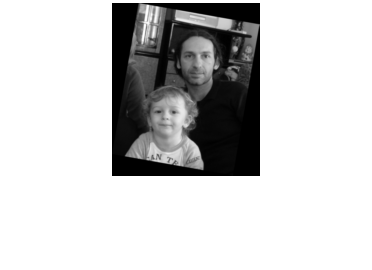

clear all;
load classifiers1000;
load boosted15; 

% load a photograph
photo = read_gray('faces4.bmp');

% rotate the photograph to make faces more upright (we 
% are cheating a bit, to save time compared to searching
% over multiple rotations).
photo2 = imrotate(photo, -10, 'bilinear');
photo2 = imresize(photo2, 0.34, 'bilinear');
figure(1); imshow(photo2, []);


% w1 and w2 are the locations of the faces, according to me.
% Used just for bookkeeping.
%w1 = photo2(40:87, 75:113);
%w2 = photo2(100:130, 47:71);

tic; result = boosted_multiscale_search(photo2, 1, boosted_classifier, weak_classifiers, [31, 25]); toc

scale = 1

Elapsed time is 0.280182 seconds.
Elapsed time is 0.285567 seconds.


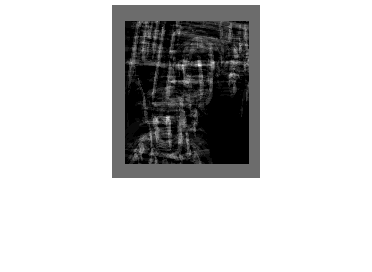

figure(2); imshow(result, []);

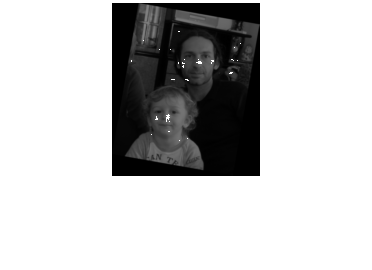

figure(3); imshow(max((result > 4) * 255, photo2 * 0.5), [])

tic; [result, boxes] = boosted_detector_demo(photo2, 1, boosted_classifier, weak_classifiers, [31, 25], 2); toc

scale = 1

Elapsed time is 0.197357 seconds.
Elapsed time is 0.243356 seconds.


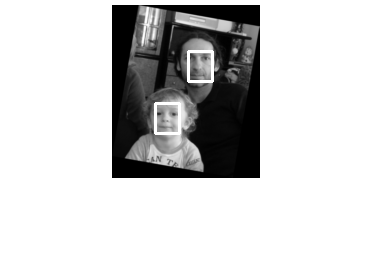

figure(2); imshow(result, []);

% load a photograph
photo = read_gray('faces4.bmp');

% rotate the photograph to make faces more upright (we 
% are cheating a bit, to save time compared to searching
% over multiple rotations).
photo2 = imrotate(photo, -10, 'bilinear');

% w1 and w2 are the locations of the faces, according to me.
% Used just for bookkeeping.
w1 = photo2(132:218, 221:290);
w2 = photo2(299:372, 133:192);

% apply the boosted detector, and get the 
% top 10 matches. Takes a few seconds on my desktop.
[result, boxes] = boosted_detector_demo(photo2, 1:0.5:3, boosted_classifier, weak_classifiers, [31, 25], 2);

scale = 1

Elapsed time is 2.050749 seconds.


scale = 1.5000

Elapsed time is 0.881309 seconds.


scale = 2

Elapsed time is 0.424374 seconds.


scale = 2.5000

Elapsed time is 0.245033 seconds.


scale = 3

Elapsed time is 0.169509 seconds.


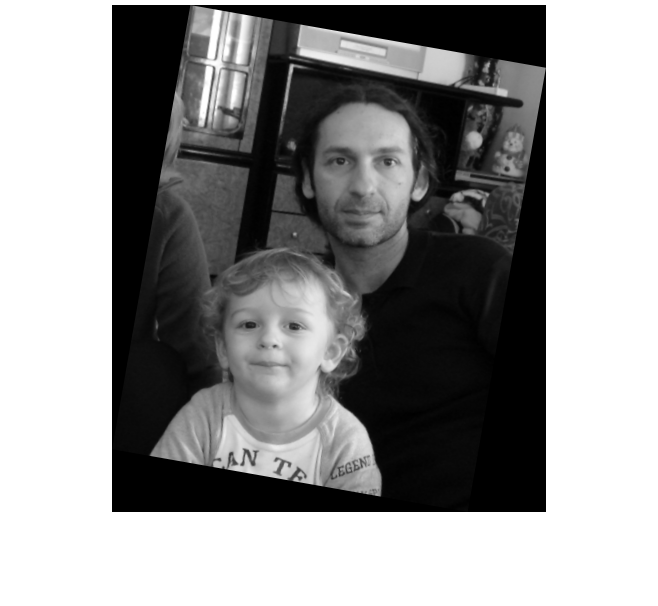

figure(1); imshow(photo2, []);

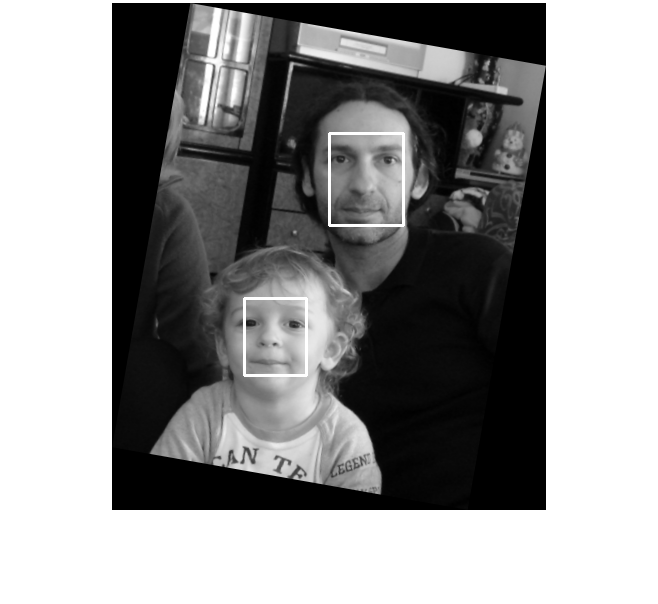

figure(2); imshow(result, [])

% correct results are: w2 at rank 25, w1 at rank 38

photo = read_gray('faces5.bmp');

% w1 is the location of the face, according to me.
% Used just for bookkeeping.
w1 = photo(110:148, 100:130);

% apply the boosted detector, and get the 
% top match.
[result, boxes] = boosted_detector_demo(photo, 1:0.5:3, boosted_classifier, weak_classifiers, [31, 25], 1);

scale = 1

Elapsed time is 1.047101 seconds.


scale = 1.5000

Elapsed time is 0.400854 seconds.


scale = 2

Elapsed time is 0.202834 seconds.


scale = 2.5000

Elapsed time is 0.126604 seconds.


scale = 3

Elapsed time is 0.082681 seconds.


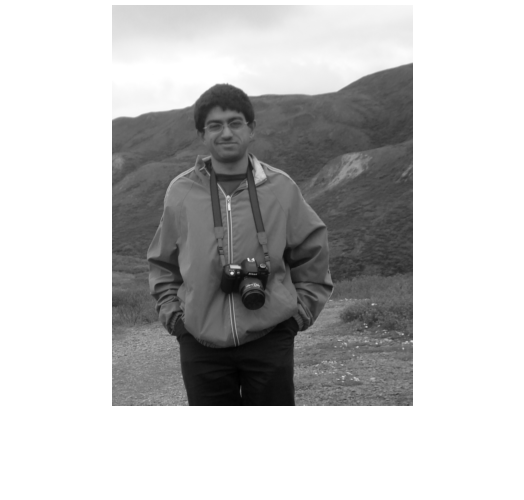

figure(1); imshow(photo, []);

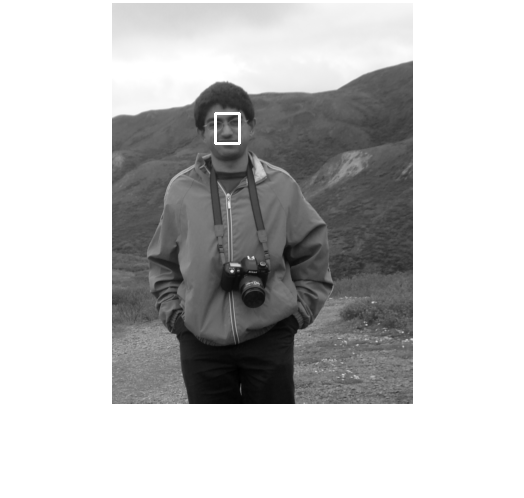

figure(2); imshow(result, [])

% rank of correct result using normalized correlation is 1.

photo = read_gray('vjm.bmp');

% apply the boosted detector, and get the 
% top 3 matches.
tic; [result, boxes] = boosted_detector_demo(photo, 1:0.5:3., boosted_classifier, weak_classifiers, [31, 25], 3); toc

scale = 1

Elapsed time is 0.516733 seconds.


scale = 1.5000

Elapsed time is 0.198145 seconds.


scale = 2

Elapsed time is 0.096603 seconds.


scale = 2.5000

Elapsed time is 0.056702 seconds.


scale = 3

Elapsed time is 0.031337 seconds.
Elapsed time is 0.038844 seconds.


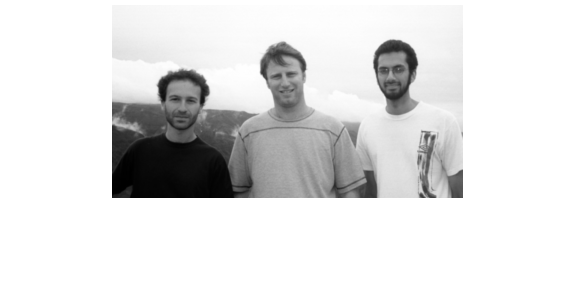

figure(1); imshow(photo, []);

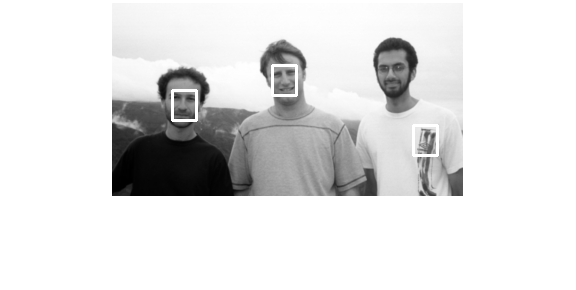

figure(2); imshow(result, [])

% rank of correct result using normalized correlation is 1.